# Exploring Behavioral Data from the Allen Brain Observatory

Both the Visual Coding Neuropixels [1] ("ephys") and Visual Coding 2P [2] ("ophys") datasets from the Allen Brain Observatory [3] consist of neural recording data collected during live behavior and visual stimulus presentation. Each neural recording has associated behavioral recordings (such as running speed & eye tracking) and behavioral stimulus parameters (the visual stimulus presentations). This tutorial walks through accessing, exploring, and visualizing Allen Brain Observatory behavioral data; and illustrates the analysis of neural recordings in the context of such behavioral data. 

## Explore Behavioral Data in the Ephys Dataset

We start by examining how behavioral data is organized in the newer Visual Coding Neuropixels dataset. 

### Select Ephys Sessions of Interest

As shown in the [EphysTutorial](matlab:open('./EphysTutorial.mlx')), the available sessions can be fetched as a table which can be "filtered" using tabular indexing: 

ephysAvailSessions = bot.listSessions('VisualCoding', 'Ephys');
ephysSessionsOfInterest = ephysAvailSessions(ephysAvailSessions.full_genotype == "wt/wt", :); % select sessions with wild-type subjects 

The Visual Coding Neuropixels dataset includes two types of [visual stimulus sets](https://allensdk.readthedocs.io/en/latest/_static/neuropixels_stimulus_sets.png). Let's explore sessions using the "Brain Observatory 1.1" stimulus set: 

ephysSessionsOfInterest = ephysSessionsOfInterest(ephysSessionsOfInterest.session_type == 'brain_observatory_1.1', :);

During some sessions, the eye tracking apparatus failed to record full or valid data. Let's exclude those sessions:

ephysSessionsOfInterest = ephysSessionsOfInterest(~ephysSessionsOfInterest.fail_eye_tracking, :)

ephysSessionsOfInterest = 13x16 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex    full_genotype                                                         structure_acronyms                                                         isi_experiment_id    date_of_acquisition     specimen_id     specimen     well_known_files     dataset_name 
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _____________    

More than a dozen sessions using the earlier "Brain Observatory 1.1" visual stimulus set are available for wild-type subjects with full behavioral data. 

### Access Behavioral Data

As described in the [EphysTutorial](matlab:open('./EphysTutorial.mlx')), we can further explore a specific session of interest by constructing a `Session` object: 

ephysSession = bot.getSessions(ephysSessionsOfInterest(1, :));
class(ephysSession)

ans = 'bot.item.concrete.EphysSession'

As with neural behavior data, behavioral data is mostly accessed through properties of the  `EphysSession` object:  

disp(ephysSession)

  EphysSession (VisualCoding) with properties:

                                id: 742951821
                              info: [1x1 struct]
                       linkedFiles: [2x1 table]

   Info Derived Values
                structure_acronyms: ["VIS"    "VISal"    "VISl"    "VISp"    "VISpm"    "VISrl"    "grey"]

   Linked Items
                            probes: [6x23 table]
                          channels: [2219x29 table]
                             units: [893x51 table]

   Linked Item Derived Values
Elapsed time is 0.030750 seconds.
       channel_structure_intervals: [18x2 table]
         structurewise_unit_counts: [7x2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[download required]'
                     invalid_times: '[download required]'
                    mean_waveforms: '[download required]'
        num_stimulus_presentations: '[download requ

For instance, the object `pupil_data` & `running_speed` properties access behavioral recording data from one of the session linked files. And various properties (e.g., `optogenetic_stimulation_epochs` &  `stimulus_presentations`)  access information about the experimental stimuli delivered. 

### Explore & Visualize Pupil Data

The `pupil_data` property represents the recorded pupil tracking data as a [timetable](https://www.mathworks.com/help/matlab/timetables.html):  

pupilData = ephysSession.pupil_data

pupilData = 288131x16 table
    timestamps    corneal_reflection_center_x    corneal_reflection_center_y    corneal_reflection_height    corneal_reflection_width    corneal_reflection_phi    pupil_center_x    pupil_center_y    pupil_height    pupil_width    pupil_phi    eye_center_x    eye_center_y    eye_height    eye_width    eye_phi 
    __________    ___________________________    ___________________________    _________________________    ________________________    ______________________    ______________    ______________    ____________    ___________</

The pupil location over time can be visualized as a location density map using a [bivariate histogram plot](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram2.html): 

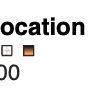

% plot a 2D histogram of pupil location
histogram2(pupilData.pupil_center_x, pupilData.pupil_center_y, 'DisplayStyle', 'tile');
xlim([200 400]);
ylim([100 300]);
cmap = copper();
colormap(cmap(end:-1:1, :));
axis square;
xlabel('x location (mm)');
ylabel('y location (mm)');
title('Pupil location');
colorbar

During this ephys session under study, the subject's pupil remain highly fixated on the visual stimulus displayed. 

### Survey the Visual Stimulus Set

The Visual Coding Neuropixels [stimulus set information](https://allensdk.readthedocs.io/en/latest/_static/neuropixels_stimulus_sets.png) details the sequence and types of visual stimuli presented to subjects during "Brain Observatory 1.1" session types.The `EphysSession` object contains properties which survey the visual stimulus set & sequence at a high-level. 

The `stimulus_names` propertry lists the stimulus types: 

stimulusTypes = ephysSession.stimulus_names

stimulusTypes = 9x1 string array
    "drifting_gratings"
    "flashes"
    "gabors"
    "invalid_presentation"
    "natural_movie_one"
    "natural_movie_three"
    "natural_scenes"
    "spontaneous"
    "static_gratings"


The `stimulus_epochs` property shows how the stimuli are organized into 15 epochs ("blocks") of stimuli of a given stimulus type, separated by short epochs without visual stimulus (spontaneous activity): 

stimulusEpochs = ephysSession.stimulus_epochs

stimulusEpochs = 30x5 timetable
       Time       start_time    stop_time    duration        stimulus_name        stimulus_block
    __________    __________    _________    ________    _____________________    ______________

    24.686 sec      24.686       84.753       60.067     "spontaneous"                 NaN      
    84.753 sec      84.753       996.75       911.99     "gabors"                        0      
    996.75 sec      996.75       1285.7       288.99     "spontaneous"                 NaN      
    1285.7 sec      1285.7       1584.3       298.52     "flashes"                       1      
    1584.3 sec      1584.3         1586       1.7514     "spontaneous"                 NaN      

### Examine the Visual Stimulus Set

The `stimulus_presentations` property represents the full visual stimulus set. 

stimuli = ephysSession.stimulus_presentations

stimuli = 70390x19 timetable
       Time       stimulus_presentation_id    stimulus_condition_id    stimulus_block_id    stimulus_block_condition_id    stimulus_name    start_time    stop_time    contrast    orientation                 phase                       size         spatial_frequency    stimulus_block    temporal_frequency    frame    x_position    y_position    color    duration
    __________    ________________________    _____________________    _________________    ___________________________    _____________    __________

As with other behavior data, the stimulus set is represented as a [timetable](https://www.mathworks.com/help/matlab/timetables.html). This timetable spans the full duration of the session which lasted over 2 hours:

hours(stimuli.Time(end))

ans = 2.5422

The timetable lists the individual stimuli ("presentations") within the contiguous blocks of a given stimulus type as surveyed above. The `stimlus_presentation_id` property is a simple zero-based index into the timetable: 

isequal(stimuli.stimulus_presentation_id',0:height(stimuli)-1)

ans = logical
   1


The `stimulus_block_id` property is a running *counter *(zero-based) of the stimuli presentations within each block:

isequal(length(find(stimuli.stimulus_block_id == 0)), length(stimulusTypes))

ans = logical
   0


The `stimulus_block_condition_id` is a running counter for each unique set of stimulus parameters (i.e., the rightward variables) within a given stimulus type (*not* a stimulus block). Each unique stimulus parameter set is a *condition *which may be repeated multiple times: 

tbl = table( ...
    'Size',[length(stimulusTypes) 2],...
    'VariableTypes',repmat("double", 2,1),...
    'VariableNames',["numStimuli" "numConditions"],...
    'RowNames',stimulusTypes);

for type = stimulusTypes'
    typeTbl = stimuli(stimuli.stimulus_name == type,:);
    tbl(type,"numStimuli") = {height(typeTbl)};
    tbl(type,"numConditions") = {numel(unique(typeTbl.stimulus_block_condition_id))}; % count the number of unique conditions per stimulus type
end
disp(tbl)

                            numStimuli    numConditions
                            __________    _____________

    drifting_gratings           630             70     
    flashes                     150              2     
    gabors                     3645            243     
    invalid_presentation          0              0     
    natural_movie_one         18000            900     
    natural_movie_three       36000           3600     
    natural_scenes             5950            119     
    spontaneous                  15              1     
    static_gratings            6000            314     



The parameters which vary across conditions differ for each stimulus type. For instance, the orientation, position, and color are varying parameters for the Gabor stimuli conditions: 

stimuliParameters = string(stimuli.Properties.VariableNames);
stimuliParameters = stimuliParameters(~contains(stimuliParameters,["stimulus_name" "id" "time" "duration"])); 

gaborStimuli = stimuli(stimuli.stimulus_name == "gabors",:);

varyingParameters = string.empty();
for parameter = stimuliParameters
    if numel(unique(gaborStimuli.(parameter))) > 1
        varyingParameters(end+1) = parameter; %#ok<SAGROW> 
    end
end
disp("For the Gabor stimuli, the following parameters vary across conditions: " + newline + join(varyingParameters));

For the Gabor stimuli, the following parameters vary across conditions: 
orientation frame x_position y_position color


The `stimulus_conditions` property returns a table identifying the presentation indices at which each unique combination of *condition* & *stimulus block *is first presented: 

ephysSession.stimulus_conditions

ans = 60594x17 table
    stimulus_condition_id    stimulus_block_condition_id    stimulus_name    contrast      mask       opacity    orientation                 phase                       size         spatial_frequency    temporal_frequency      units      frame    x_position    y_position      color_triplet      color
    _____________________    ___________________________    _____________    ________    _________    _______    ___________    ________________________________    ______________    _________________    _______

### Obtain Behavior-Informed Neural Spike Data 

The `EphysSession` object has several [methods](https://www.mathworks.com/help/matlab/methods-defining-operations.html) pertaining to the session' stimulus set information: 

methods(ephysSession)

Methods for class bot.item.concrete.EphysSession:

EphysSession                     getConditionsByStimulusName      getConditionwiseSpikeStatistics  getDatasetName                   getDatasetType                   getPresentationwiseSpikeCounts   getPresentationwiseSpikeTimes    getStimulusEpochsByDuration      raise_MultipleProbes_warning     

Methods of bot.item.concrete.EphysSession inherited from handle.



Three of these methods quantify neural spike data in reference to the visual stimulus information: 

- `getConditionwiseSpikeStatistics()` computes spike statistics on data grouped by stimulus conditions

- `getPresentationwiseSpikeCounts()`  returns spike counts aligned by stimulus presentations

- `getPresentationwiseSpikeTimes()` returns a table of spike times aligned by stimulus presentations

These methods operating across all the `Unit` objects linked to this `EphysSession` object. These methods are most useful (and faster) when indexed by specific units & presentations. For reference, let's examine the `spike_times` property which contains timestamps of the detected spikes for each unit: 

head(ephysSession.spike_times)

     unit_id       spike_times   
    _________    ________________

    950960902    {12242x1 double}
    950961023    {31602x1 double}
    950962197    {15309x1 double}
    950961313    {16804x1 double}
    950961303    {17063x1 double}
    950960934    {16835x1 double}
    950960918    {23077x1 double}
    950962078    { 4280x1 double}



Let's invoke `getPresentationwiseSpikeTimes()` during Gabor stimuli for the most sparsely firing unit in this selection: 

unitID = 950962078; % most sparsely firing unit from selection above
gaborStims = stimuli(stimuli.stimulus_name == "static_gratings", :);
gaborPresentationIDs = gaborStims.stimulus_presentation_id;

ephysSession.getPresentationwiseSpikeTimes(gaborPresentationIDs,unitID)

ans = 686x4 table
    spike_times    stimulus_presentation_id     unit_id     time_since_stimulus_presentation_onset
    ___________    ________________________    _________    ______________________________________

        5403                49449              950962078                   0.018358               
      5407.3                49466              950962078                    0.13487               
      5409.6                49475              950962078                    0.16439               
      5412.6                49487              950962078                    0.10529               
      5413.1                49489              950962078                    0.10603               
      5414.7                49496              950962078                   0.025116               
        5420                49517              950962

Over 600 spikes from this unit occurred during Gabor stimulus presentations. This presentation-wise table includes the spike times relative to the presentation onset in the final column. See the [EphysDemo](matlab:open('..\demos\EphysDemo.mlx')) for an example of computing a peristimulus time histogram (PSTH) from such stimulus-aligned spike times. 

## Exploring Behavioral Data in the Ophys Dataset

The visual stimulus concepts are similar for the Visual Coding 2P dataset ("ophys"); however some details of the `OphysSession` object interface differ. 

### Access Behavioral Data

As with the Visual Coding Neuropixels dataset above, a `Session `object is first constructed from among the ophys sessions of interest: 

availOphysSessions = bot.listSessions('VisualCoding', 'Ophys');
ophysSessionsOfInterest = availOphysSessions(ismember(availOphysSessions.targeted_structure_acronym, categorical(["VISal" "VISrl" "VISam"])), :);
ophysSessionsOfInterest = ophysSessionsOfInterest(ophysSessionsOfInterest.cre_line == "Cux2-CreERT2", :);
ophysSessionsOfInterest = ophysSessionsOfInterest(ophysSessionsOfInterest.imaging_depth == 175,:);
ophysSessionsOfInterest = ophysSessionsOfInterest(~ophysSessionsOfInterest.fail_eye_tracking, :);
ophysSessionsOfInterest = ophysSessionsOfInterest(ophysSessionsOfInterest.session_type == "three_session_A", :);
ophysSession = bot.getSessions(ophysSessionsOfInterest(1,:));

Downloaded 440 MB/440 MB (100%). Completed in 20 seconds. 
Reading table from file...done


As with the ephys sessions above, only ophys sessions with false values of `fail_eye_tracking ``are `considered. Note there is no **session_type **variable, sd all the Visual Coding 2P sessions used the original "Brain Observatory 1.1" visual stimulus set. 

Once an `OphysSession` object is created, behavioral data including stimulus set information is again accessed through its properties: 

disp(ophysSession)

  OphysSession (VisualCoding) with properties:

                                     id: 503412730
                                   info: [1x1 struct]
                           session_type: three_session_A
                            linkedFiles: [2x1 table]

   Linked Items
                             experiment: [1x1 bot.item.Experiment]
                                  cells: [161x94 table]

   Linked File Values ('SessNWB')
                      cell_specimen_ids: '[download required]'
          corrected_fluorescence_traces: '[download required]'
                fluorescence_timestamps: '[download required]'
                    fluorescence_traces: '[download required]'
            fluorescence_traces_demixed: '[download required]'
                fluorescence_traces_dff: '[download required]'
                         max_projection: '[download required]'
                      motion_corre

While some behavior-related properties (e.g. **running_speed**) are unchanged, others such as the eyetracking (pupil) data & stimulus set information are named and represented differently. 

#### Examine Pupil Data

Rather than a single property consolidating pupil data, the `OphysSession `represents the recorded eye tracking data across the `pupil_location `and `pupil_size `properties: 

pupilSize = ophysSession.pupil_size

pupilSize = 115744x1 timetable
    timestamps    pupil_areas
    __________    ___________

    9.9738 sec        3484   
    10.007 sec      3473.7   
    10.04 sec       3302.8   
    10.073 sec      3407.1   
    10.106 sec      3358.8   
    10.14 sec       3307.3   
    10.173 sec      3528.2   
    10.206 sec      3304.4   
    10.239 sec      3229.4   
    10.272 sec      3482.3   
    10.305 sec      3307.3   
    10.339 sec      3362.6   
    10.372 sec      3240.5   
    10.405 sec      3292.4   
    10.438 sec      3336.4   
    10.471 sec      3245.3   


pupilLocation = ophysSession.pupil_location

pupilLocation = 115744x2 timetable
    timestamps    theta (deg)    phi (deg)
    __________    ___________    _________

    9.9738 sec      -17.232       24.314  
    10.007 sec      -17.236       24.374  
    10.04 sec       -16.951       24.561  
    10.073 sec      -16.645       24.419  
    10.106 sec      -16.646       24.698  
    10.14 sec       -16.825       24.476  
    10.173 sec      -17.181       24.511  
    10.206 sec      -16.823       24.327  
    10.239 sec      -16.661       24.408  
    10.272 sec      -17.239       24.426  
    10.305 sec      -16.942       24.335  
    10.339 sec      -17.106       24.325  
    10.372 sec      -17.009       24.48

Both properties return [timetable](https://www.mathworks.com/help/matlab/timetables.html) objects, with identical timestamps:

isequal(pupilSize.timestamps, pupilLocation.timestamps)

ans = logical
   1


#### Accessing Stimulus Information

For  `OphysSession `objects, the stimulus types are available via the `stimulus_list` property: 

ophysSession.stimulus_list

ans = 1x4 cell array
    {'drifting_gratings'}    {'natural_movie_one'}    {'natural_movie_three'}    {'spontaneous'}


The pirmary difference for `OphySession` objects is that a method -- `getStimulusTable()` -- is used rather than a property to obtain the tabular listing of stimulus presentations.This method returns listings for one specified stimulus type at a time, rather than the full stimulus list at once: 

getStimulusTable(ophysSession,'drifting_gratings')

ans = 628x6 timetable
    start_time    temporal_frequency    orientation    blank_sweep    start_frame    end_frame     duration 
    __________    __________________    ___________    ___________    ___________    _________    __________

    34.321 sec             1                270             0             735           795       1.9903 sec
    37.307 sec             4                135             0             825           885       1.9902 sec
    40.325 sec            15                 90             0             916           976       1.9903 sec
    43.311 sec             2                225             0            1006          1066       1.9903 sec
    46.32

### Learn More

See the [EphysTutorial](matlab:open('./EphysTutorial.mlx')) and the [OphysTutorial](matlab:open('./OphysTutorial.mlx')) to learn about accessing, exploring, and visualizing neural data from the respective Allen Brain Observatory datasets.

See the [EphysDemo](matlab:open('../demos/EphysDemo.mlx')) and [OphysDemo](matlab:open('../demos/OphysDemo.mlx')) for examples of neural data analysis combining both the neural and behavioral data from the respective Allen Brain Observatory datasets. 

### References

[1] Copyright 2016 Allen Institute for Brain Science. Visual Coding 2P dataset. Available from: [http://portal.brain-map.org/explore/circuits/visual-coding-2p](http://portal.brain-map.org/explore/circuits/visual-coding-2p).

[2] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[3] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[1] [https://allensdk.readthedocs.io/en/latest/visual_behavior_optical_physiology.html](https://allensdk.readthedocs.io/en/latest/visual_behavior_optical_physiology.html).

[2] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_session.html](https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_session.html).